# Dynamic Experiment

clear;
close all;
clc;
G=0;

### choose anchor and sensor

anchor=[1,2,3,4,5,6,7,8];
sensor=[1,2,3];

## 1. Load Data

a0=[-3.420,3.005];
a1=[0.002,3.011];
a2=[3.606,2.979];
a3=[3.601,-0.001];
a4=[3.567,-3.009];
a5=[-0.007,-2.965];
a6=[-3.467,-2.959];
a7=[-3.486,-0.010];
A0=[a0;a1;a2;a3;a4;a5;a6;a7];
A0=A0';
s0=[-0.068924,-0.142294];
s1=[-0.075036,0.140209];
s2=[0.203416,0.145076];
S0=[s0;s1;s2];
S0=S0';

bias0=readmatrix('../4. bias calibration/bias.xlsx');
slope0=readmatrix('../4. bias calibration/slope.xlsx');
sigma0=readmatrix('../4. bias calibration/sigma.xlsx');

A=[];
S=[];
bias=[];
slope=[];
sigma=[];
sigma_square=[];
for i=1:length(anchor)
    A=[A,A0(:,anchor(i))];
end
for i=1:length(sensor)
    S=[S,S0(:,sensor(i))];
end
for i=1:length(sensor)
    for j=1:length(anchor)
        bias=[bias;bias0((sensor(i)-1)*8+anchor(j))];
        slope=[slope;slope0((sensor(i)-1)*8+anchor(j))];
        sigma=[sigma;sigma0((sensor(i)-1)*8+anchor(j))];
    end
end

path={'../3. preprocessed dataset/Dynamic preprocessed dataset/'};
UWBfile={'UWB_dynamic_exp_fast','UWB_dynamic_exp_mid','UWB_dynamic_exp_slow'};
OPTfile={'motion_capture_dynamic_exp_fast','motion_capture_dynamic_exp_mid','motion_capture_dynamic_exp_slow'};
velocity={'fast','mid','slow'};

for u=1:length(UWBfile)
    UWBfile_name=strcat(path+string(UWBfile(u)),'.xlsx');
    OPTfile_name=strcat(path+string(OPTfile(u)),'.xlsx');
    UWBdata=readmatrix(UWBfile_name);
    opt_data=readmatrix(OPTfile_name);
    UWBdata(:,1)=[];
    opt_data(:,1)=[];

    uwb_data=[];
    for i=1:length(sensor)
        for j=1:length(anchor)
            uwb_data=[uwb_data,UWBdata(:,(sensor(i)-1)*8+anchor(j))];
        end
    end

    position_data=opt_data(:,[1,2]);
    t=position_data';
    yaw=opt_data(:,3);

    R=zeros(2,2,length(yaw));
    Sa=zeros(2,length(sensor),length(yaw));
    for i=1:length(yaw)
        R(:,:,i)=[cosd(yaw(i)),-sind(yaw(i));sind(yaw(i)),cosd(yaw(i))];
        Sa(:,:,i)=R(:,:,i)*S+t(:,i);
    end

## 2. Eliminate UWB ranging errors 

    data_number=length(uwb_data);
    uwb_data=(uwb_data-bias')./repmat(1+slope',data_number,1);

## 3. Sate Estimate

    M=length(anchor); %3 anchors
    N=length(sensor); %2 sensors

    uwb_distance=uwb_data';

    R0=zeros(2,2,data_number);
    t0=zeros(2,data_number);
    Re=zeros(2,2,data_number);
    te=zeros(2,data_number);
    Rm=zeros(2,2,data_number);
    tm=zeros(2,data_number);
    R1=zeros(2,2,data_number);
    t1=zeros(2,data_number);
    R2=zeros(2,2,data_number);
    t2=zeros(2,data_number);
    
    mse_R0_c=zeros(data_number-2*G,2*G+1);
    mse_R0_a=zeros(data_number-2*G,2*G+1);
    mse_t0=zeros(data_number-2*G,2*G+1);
    mse_Re_c=zeros(data_number-2*G,2*G+1);
    mse_Re_a=zeros(data_number-2*G,2*G+1);
    mse_te=zeros(data_number-2*G,2*G+1);
    mse_Rm_c=zeros(data_number-2*G,2*G+1);
    mse_Rm_a=zeros(data_number-2*G,2*G+1);
    mse_tm=zeros(data_number-2*G,2*G+1);
    mse_R1_c=zeros(data_number-2*G,2*G+1);
    mse_R1_a=zeros(data_number-2*G,2*G+1);
    mse_t1=zeros(data_number-2*G,2*G+1);
    mse_R2_c=zeros(data_number-2*G,2*G+1);
    mse_R2_a=zeros(data_number-2*G,2*G+1);
    mse_t2=zeros(data_number-2*G,2*G+1);

    dis=0;
    V=zeros(1,data_number-1);
    
    Y0_r=zeros(data_number-2*G,2*G+1,3);
    Ye_r=zeros(data_number-2*G,2*G+1,3);
    Ym_r=zeros(data_number-2*G,2*G+1,3);
    Y1_r=zeros(data_number-2*G,2*G+1,3);
    Y2_r=zeros(data_number-2*G,2*G+1,3);

    Pe_1=zeros(2,data_number);
    Pe_2=zeros(2,data_number);
    P_1=zeros(2,data_number);
    P_2=zeros(2,data_number);
    Ze=zeros(2,3,data_number);
    Z=zeros(2,3,data_number);

#### ULS- precalculation  

    D_bar=zeros((M-1)*N,1);
    A_bar=A-(A*ones(M,1))*ones(1,M)/M;
    Psi=[0,1;1,0;-1,0;0,1];%(4,2)
    H1=-2*kron(S',A_bar')*Psi;    %(N*(M-1),2)
    H2=repmat(-2*A_bar',N,1); %(N*(M-1),2)
    H=[H1,H2];       %(N*(M-1),4)
    HtH_invHt=(H'*H)\H';
    Sigma=(sigma./(1+slope))';
    W=1./(Sigma.^2);

#### SDP

    c_norm = repmat((vecnorm(S))',M,1); %(M*N,1),||c||        
    C=zeros(M*N,1);
    for i=1:N
        C((i-1)*M+1:i*M,:)=c_norm(i).^2;
    end

#### **GTRS**

    DD_bar=zeros(M*N,1);
    E1=zeros(N*M,2);
    E2=zeros(N*M,2);
    for i=1:N
        sigma_M=Sigma((i-1)*M+1:i*M);
        TAt= A'-ones(M,1)*((1./sigma_M.^2)*A')/(sum(1./sigma_M.^2));
        E1((i-1)*M+1:i*M,:)=-2*(kron(S(:,i)',TAt))*Psi; %NM*2
        E2((i-1)*M+1:i*M,:)=-2*TAt; %NM*2
    end

### Estimate

    for k=1:data_number
        d=uwb_distance(:,k);
        d_square=d.^2;
        
        %ULS
        D=d_square-(vecnorm(repmat(A,1,N))').^2-(Sigma').^2;
        for i=1:N
            D_bar((i-1)*M+1:i*M,:)= D((i-1)*M+1:i*M,:)-ones(M,1)*(ones(1,M)*D((i-1)*M+1:i*M,:))/M;
        end
        [R0(:,:,k),t0(:,k)]= estimator(D_bar,HtH_invHt);

        %GN-ULS
        [Re(:,:,k),te(:,k)]=Gauss_Newton(R0(:,:,k),t0(:,k),A,S,d,W);

        %multiGN-ULS
        Rm(:,:,k)=Re(:,:,k);
        tm(:,k)=te(:,k);
        for r=1:10
            [Rm(:,:,k),tm(:,k)]=Gauss_Newton(Rm(:,:,k),tm(:,k),A,S,d,W);
        end

        %GN-SDP
%         d1=d_square-(vecnorm(repmat(A,1,N))').^2-C;%(M*N,1)
% %         diagonal=1./(4*(d.*Sigma').^2+2*(Sigma').^4);
%         Rn=4*(d.*Sigma').^2;
%         diagonal=1./Rn;%Ignore second-order noise
%         [R1(:,:,k),t1(:,k)]= SDP(A,S,d1,diagonal);
%         [R1(:,:,k),t1(:,k)]=Gauss_Newton(R1(:,:,k),t1(:,k),A,S,d,W);
        R1(:,:,k)=R0(:,:,k);
        t1(:,k)=t0(:,k);

        %GTRS-1
%         DD=d_square-(vecnorm(repmat(A,1,N))').^2;   %ignore the quadratic noise
%         for i=1:N
%             DD_bar((i-1)*M+1:i*M,:)=DD((i-1)*M+1:i*M,:)-ones(M,1)*( ((1./sigma_M.^2)*DD((i-1)*M+1:i*M,:))/ (sum(1./sigma_M.^2)) );
%         end
%         [y20,t20]=GTRS(E1,E2,Rn,DD_bar,M,N);
%         R20=[y20(2),-y20(1);y20(1),y20(2)];
%         %GTRS-2
%         DDD=zeros(M*N,1);
%         F1=zeros(M*N,2);
%         F2=zeros(M*N,2);
%         for i=1:N
%             DDD((i-1)*M+1:i*M,:)=d_square((i-1)*M+1:i*M,:)-vecnorm(t20-A)'.^2-norm(S(:,i)).^2;
%             F1((i-1)*M+1:i*M,:)=2*kron(S(:,i)',(t20-A)')*Psi;
%             F2((i-1)*M+1:i*M,:)=2*(repmat(R20*S(:,i)+t20,1,M)'-A');
%         end
%         [y2,dt2]=GTRS(F1,F2,Rn,DDD,M,N);
%         R2(:,:,k)=[y2(2),-y2(1);y2(1),y2(2)];
%         t2(:,k)=t20+dt2;
        R2(:,:,k)=R0(:,:,k);
        t2(:,k)=t0(:,k);

        if k==1
        else
            V(k-1)=norm(t(:,k)-t(:,k-1))/0.01;
            dis=dis+norm(t(:,k)-t(:,k-1));
        end

        %Draw
        Pe_1(:,k)=Re(:,1,k)*0.3*0.75;
        Pe_2(:,k)=Re(:,2,k)*0.1*0.75;
        P_1(:,k)=R(:,1,k)*0.3;
        P_2(:,k)=R(:,2,k)*0.1;

        Ze(1,:,k)=[te(1,k)+Pe_1(1,k),te(1,k)+Pe_2(1,k),te(1,k)-Pe_2(1,k)];
        Ze(2,:,k)=[te(2,k)+Pe_1(2,k),te(2,k)+Pe_2(2,k),te(2,k)-Pe_2(2,k)];
        Z(1,:,k)=[t(1,k)+P_1(1,k),t(1,k)+P_2(1,k),t(1,k)-P_2(1,k)];
        Z(2,:,k)=[t(2,k)+P_1(2,k),t(2,k)+P_2(2,k),t(2,k)-P_2(2,k)];

        if mod(k,1000)==0 %iteration tracking
            k
        end
    end

k =         1000


k =         2000


k =         3000


k =         4000


k =         5000


k =         6000


k =         7000


k =         8000


k =         9000


k =        10000


k =        11000


k =        12000


k =        13000


k =         1000


k =         2000


k =         3000


k =         4000


k =         5000


k =         6000


k =         7000


k =         8000


k =         9000


k =        10000


k =        11000


k =        12000


k =         1000


k =         2000


k =         3000


k =         4000


k =         5000


k =         6000


k =         7000


k =         8000


k =         9000


k =        10000


k =        11000


k =        12000


k =        13000


k =        14000


k =        15000


k =        16000


k =        17000


k =        18000


k =        19000


k =        20000


k =        21000


k =        22000


k =        23000


k =        24000


k =        25000


k =        26000


k =        27000


k =        28000


k =        29000


k =        30000


k =        31000


###     3.4 RMSE

    for g=G:-1:1
        for k=1+G:data_number-G
            %MSE
            %ULS
            mse_R0_c(k-G,G-g+1)=norm(R0(:,:,k-g)-R(:,:,k),'fro')^2;
            mse_R0_a(k-G,G-g+1)=angular_distance(R0(:,:,k-g),R(:,:,k))^2;
            mse_t0(k-G,G-g+1)=norm(t0(:,k-g)-t(:,k))^2;
            %GN-ULS
            mse_Re_c(k-G,G-g+1)=norm(Re(:,:,k-g)-R(:,:,k),'fro')^2;
            mse_Re_a(k-G,G-g+1)=angular_distance(Re(:,:,k-g),R(:,:,k))^2;
            mse_te(k-G,G-g+1)=norm(te(:,k-g)-t(:,k))^2;
            %multiGN-ULS
            mse_Rm_c(k-G,G-g+1)=norm(Rm(:,:,k-g)-R(:,:,k),'fro')^2;
            mse_Rm_a(k-G,G-g+1)=angular_distance(Rm(:,:,k-g),R(:,:,k))^2;
            mse_tm(k-G,G-g+1)=norm(tm(:,k-g)-t(:,k))^2;
            %GN-SDP
            mse_R1_c(k-G,G-g+1)=norm(R1(:,:,k-g)-R(:,:,k),'fro')^2;
            mse_R1_a(k-G,G-g+1)=angular_distance(R1(:,:,k-g),R(:,:,k))^2;
            mse_t1(k-G,G-g+1)=norm(t1(:,k-g)-t(:,k))^2;
            %GTRS
            mse_R2_c(k-G,G-g+1)=norm(R2(:,:,k-g)-R(:,:,k),'fro')^2;
            mse_R2_a(k-G,G-g+1)=angular_distance(R2(:,:,k-g),R(:,:,k))^2;
            mse_t2(k-G,G-g+1)=norm(t2(:,k-g)-t(:,k))^2;            
        end
        %ULS
        Y0_r(:,G-g+1,1)=sqrt(mse_R0_c(:,G-g+1));
        Y0_r(:,G-g+1,2)=sqrt(mse_R0_a(:,G-g+1));
        Y0_r(:,G-g+1,3)=sqrt(mse_t0(:,G-g+1));
        %GN-ULS
        Ye_r(:,G-g+1,1)=sqrt(mse_Re_c(:,G-g+1));
        Ye_r(:,G-g+1,2)=sqrt(mse_Re_a(:,G-g+1));
        Ye_r(:,G-g+1,3)=sqrt(mse_te(:,G-g+1));
        %multiGN-ULS
        Ym_r(:,G-g+1,1)=sqrt(mse_Rm_c(:,G-g+1));
        Ym_r(:,G-g+1,2)=sqrt(mse_Rm_a(:,G-g+1));
        Ym_r(:,G-g+1,3)=sqrt(mse_tm(:,G-g+1));
        %GN-SDP
        Y1_r(:,G-g+1,1)=sqrt(mse_R1_c(:,G-g+1));
        Y1_r(:,G-g+1,2)=sqrt(mse_R1_a(:,G-g+1));
        Y1_r(:,G-g+1,3)=sqrt(mse_t1(:,G-g+1));
        %GTRS
        Y2_r(:,G-g+1,1)=sqrt(mse_R2_c(:,G-g+1));
        Y2_r(:,G-g+1,2)=sqrt(mse_R2_a(:,G-g+1));
        Y2_r(:,G-g+1,3)=sqrt(mse_t2(:,G-g+1));
    end
    for g=1:G+1
        for k=1+G:data_number-G
            %MSE
            %ULS
            mse_R0_c(k-G,G+g)=norm(R0(:,:,k+g-1)-R(:,:,k),'fro')^2;
            mse_R0_a(k-G,G+g)=angular_distance(R0(:,:,k+g-1),R(:,:,k))^2;
            mse_t0(k-G,G+g)=norm(t0(:,k+g-1)-t(:,k))^2;
            %GN-ULS
            mse_Re_c(k-G,G+g)=norm(Re(:,:,k+g-1)-R(:,:,k),'fro')^2;
            mse_Re_a(k-G,G+g)=angular_distance(Re(:,:,k+g-1),R(:,:,k))^2;
            mse_te(k-G,G+g)=norm(te(:,k+g-1)-t(:,k))^2;
            %multiGN-ULS
            mse_Rm_c(k-G,G+g)=norm(Rm(:,:,k+g-1)-R(:,:,k),'fro')^2;
            mse_Rm_a(k-G,G+g)=angular_distance(Rm(:,:,k+g-1),R(:,:,k))^2;
            mse_tm(k-G,G+g)=norm(tm(:,k+g-1)-t(:,k))^2;
            %GN-SDP
            mse_R1_c(k-G,G+g)=norm(R1(:,:,k+g-1)-R(:,:,k),'fro')^2;
            mse_R1_a(k-G,G+g)=angular_distance(R1(:,:,k+g-1),R(:,:,k))^2;
            mse_t1(k-G,G+g)=norm(t1(:,k+g-1)-t(:,k))^2;
            %GTRS
            mse_R2_c(k-G,G+g)=norm(R2(:,:,k+g-1)-R(:,:,k),'fro')^2;
            mse_R2_a(k-G,G+g)=angular_distance(R2(:,:,k+g-1),R(:,:,k))^2;
            mse_t2(k-G,G+g)=norm(t2(:,k+g-1)-t(:,k))^2;
        end
        %ULS
        Y0_r(:,G+g,1)=sqrt(mse_R0_c(:,G+g));
        Y0_r(:,G+g,2)=sqrt(mse_R0_a(:,G+g));
        Y0_r(:,G+g,3)=sqrt(mse_t0(:,G+g));
        %GN-ULS
        Ye_r(:,G+g,1)=sqrt(mse_Re_c(:,G+g));
        Ye_r(:,G+g,2)=sqrt(mse_Re_a(:,G+g));
        Ye_r(:,G+g,3)=sqrt(mse_te(:,G+g));
        %multiGN-ULS
        Ym_r(:,G+g,1)=sqrt(mse_Rm_c(:,G+g));
        Ym_r(:,G+g,2)=sqrt(mse_Rm_a(:,G+g));
        Ym_r(:,G+g,3)=sqrt(mse_tm(:,G+g));
        %GN-SDP
        Y1_r(:,G+g,1)=sqrt(mse_R1_c(:,G+g));
        Y1_r(:,G+g,2)=sqrt(mse_R1_a(:,G+g));
        Y1_r(:,G+g,3)=sqrt(mse_t1(:,G+g));
        %GTRS
        Y2_r(:,G+g,1)=sqrt(mse_R2_c(:,G+g));
        Y2_r(:,G+g,2)=sqrt(mse_R2_a(:,G+g));
        Y2_r(:,G+g,3)=sqrt(mse_t2(:,G+g));
    end
    V_mean=dis/data_number*100;
    RMSE_R_ULS=mean(Y0_r(:,:,2));
    RMSE_R_GN_ULS=mean(Ye_r(:,:,2));
    RMSE_R_multiGN_ULS=mean(Ym_r(:,:,2));
    RMSE_R_SDP=mean(Y1_r(:,:,2));
    RMSE_R_GTRS=mean(Y2_r(:,:,2));
    RMSE_t_ULS=mean(Y0_r(:,:,3)*100);
    RMSE_t_GN_ULS=mean(Ye_r(:,:,3)*100);
    RMSE_t_multi_UCLS=mean(Ym_r(:,:,3)*100);
    RMSE_t_SDP=mean(Y1_r(:,:,3)*100);
    RMSE_t_GTRS=mean(Y2_r(:,:,3)*100);

    u

u =      1


u =      2


u =      3


    min_R=25

min_R =     25


min_R =     25


min_R =     25


    min_t=find(RMSE_t_GN_ULS==min(RMSE_t_GN_ULS))-(G+1)

min_t =      0


min_t =      0


min_t =      0


%     save('Trial1_plot_'+string(velocity(u))+'.mat','Y0_r','Ye_r','Ym_r','Y1_r','Y2_r','Z','Ze','u','RMSE_R_GN_ULS','RMSE_t_GN_ULS', ...
%         "RMSE_t_GTRS","RMSE_t_SDP","RMSE_t_GTRS","RMSE_R_SDP","RMSE_R_GTRS",'RMSE_R_ULS','RMSE_t_ULS',...
%         'RMSE_R_multiGN_ULS','RMSE_t_multi_UCLS','time_2','time_1','time_m','time_e','time_0','min_t','min_R','t','te',"t0",'tm',"t1",'t2')

## 4. Plot

### 4.1

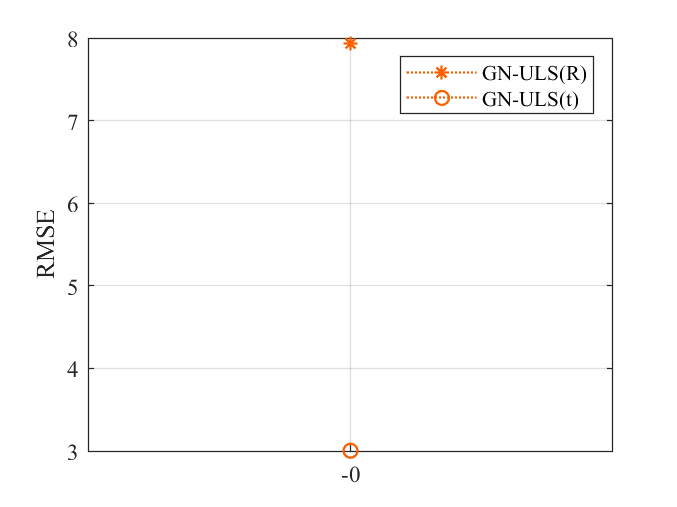

    figure(1)
    plot(RMSE_R_GN_ULS,':*','LineWidth',1,'MarkerSize',6,'Color','#fd5f00')
    hold on
    plot(RMSE_t_GN_ULS,':o','LineWidth',1,'MarkerSize',6,'Color','#fd5f00')
    hold off
    
    set(gca,'Fontname', 'Times New Roman')
    set(gca,'XTick',1:10:2*G+1)
    set(gca,'XTicklabel',-G:10:G)
    ylabel('RMSE')
    legend('GN-ULS(R)','GN-ULS(t)','Location','northeast')
    grid on
    saveas(gcf,strcat('Image\'+string(velocity(u))+'_min(RMSE).png'));

### 4.2 RMSE

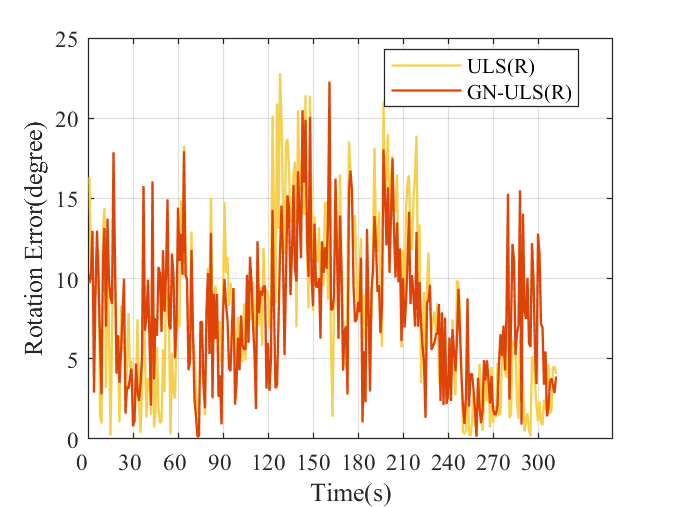

    aaa=1:100:data_number;
    figure(2) 
    plot(Y0_r(aaa,2),'LineWidth',1,'Color','#f6d04d')
    hold on
    plot(Ye_r(aaa,2),'LineWidth',1,'Color','#de4307')
    hold off

    set(gca,'Fontname', 'Times New Roman')
    set(gca,'XTick',0:30:length(Z)/100);
    set(gca,'XTicklabel',0:30:length(Z)/100)
    ylabel('Rotation Error(degree)')
    xlabel('Time(s)')
    legend('ULS(R)','GN-ULS(R)','Location','Best')
    grid on
    saveas(gcf,strcat('Image\'+string(velocity(u))+'_RMSE(R).png'));


    figure(3)
    plot(Y0_r(aaa,3)*100,'LineWidth',1,'Color','#f6d04d')
    hold on
    plot(Ye_r(aaa,3)*100,'LineWidth',1,'Color','#de4307')
    hold off

    set(gca,'Fontname', 'Times New Roman')
    set(gca,'XTick',0:30:length(Z)/100);
    set(gca,'XTicklabel',0:30:length(Z)/100)
    ylabel('Translation Error(cm)')
    xlabel('Time(s)')
    legend('ULS(t)','GN-ULS(t)','Location','Best')
    grid on
    saveas(gcf,strcat('Image\'+string(velocity(u))+'_RMSE(t).png'));

### 4.3 Trajectories

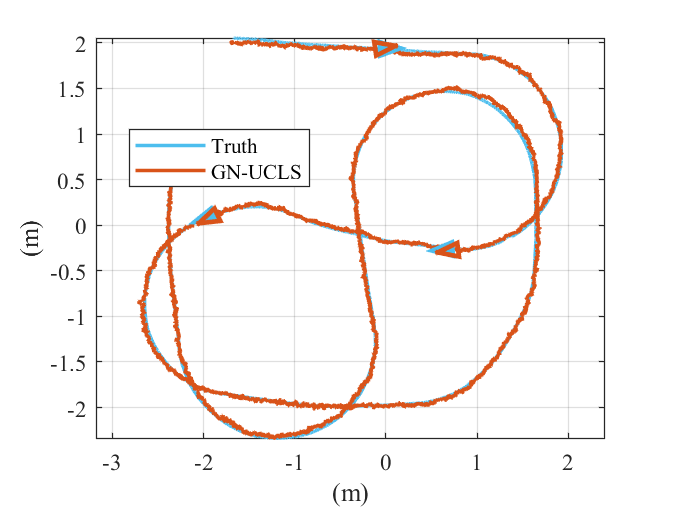

    figure(3)
    plot(t(1,:),t(2,:),'LineWidth',1.5,'Color','#4DBEEE');
    hold on
    plot(te(1,:),te(2,:),'LineWidth',1.5,'Color','#D95319');
    hold on
    patch('Faces',[1 2 3],'Vertices',Z(:,:,7000)','EdgeColor','#4DBEEE','FaceColor','#4DBEEE')
    hold on
    patch('Faces',[1 2 3],'Vertices',Ze(:,:,7000)','EdgeColor','#D95319','FaceColor','none','LineWidth',2)
    hold on
    patch('Faces',[1 2 3],'Vertices',Z(:,:,2000)','EdgeColor','#4DBEEE','FaceColor','#4DBEEE')
    hold on
    patch('Faces',[1 2 3],'Vertices',Ze(:,:,2000)','EdgeColor','#D95319','FaceColor','none','LineWidth',2)
    hold on
    patch('Faces',[1 2 3],'Vertices',Z(:,:,10000)','EdgeColor','#4DBEEE','FaceColor','#4DBEEE')
    hold on
    patch('Faces',[1 2 3],'Vertices',Ze(:,:,10000)','EdgeColor','#D95319','FaceColor','none','LineWidth',2)
    hold off
    
    set(gca,'Fontname', 'Times New Roman')
    xlabel('(m)');
    ylabel('(m)')
    legend('Truth','GN-UCLS','Location','Best')
    axis equal
    grid on
    saveas(gcf,strcat('Image\'+string(velocity(u))+'_trajectory.png'));   

end